clc;
clear;
close all;

## 添加路径

addpath('plane wave\')

## 参数设置

# Gaussian Beam

lambda=561e-6;
beamSize=1.6;       %初始高斯光束腰斑直径
beamStd=beamSize/2;
beam=GaussianBeam(5,beamStd,lambda);
color=wavelength2color(lambda*10^6, 'gammaVal', 2.2, 'maxIntensity', 255, 'colorSpace', 'rgb');
color=gpuArray(color);

# MLA

rla=-2.1;% 透镜1的曲率半径           
d = 2.4;              % 透镜单元边长
t = 1.2;            % 透镜厚度
N=2010;% 微透镜单元采样点数
material={"D-K9"};
MLA1=Lens([inf,-rla],t,d,material,lambda);
num=floor(beamStd/d*5);            %数量
if num==0
    num=1;
end
area1 = num*d;           % 光场的面积
area2=1;
area3=5;
rate=(d/N);           %采样率（global）
area2=findClosestDivisible(area2,rate);
times=500;
peak=0;
SD=0;

distance1 =3;   % 投影距离

# Fourier Lens

rfl1 = -557.400;            % 傅里叶透镜的曲率半径（胶合透镜）
rfl2 = -137.090;
rfl3 = 165.2;
dfl = 40;              % 傅里叶透镜直径
Dfl = area2;              %采样区域
tfl = [2,4];            % 傅里叶透镜厚度
material_fl={'SF2','N-BK7'};

FL=Lens([rfl1,rfl2,rfl3],tfl,dfl,material_fl,lambda);

# Diffuser

diffuserAngle=2.5;   %散射片散射角度
diffuser=Diffuser(diffuserAngle,lambda);

# Objective Lens

n_oil=1;
f_TL=200;
beta=100;
f_OBJ=f_TL/beta;
NA=1.49;
rate2=1/area3*lambda*f_TL;%管镜焦面采样率
area4=(rate2*area3/rate);%管镜焦面计算大小
rate3=1/area4*lambda*f_OBJ/n_oil;%样品面采样率
rP=f_OBJ*NA;
mask=drawCircle(rP/rate2,0,0,round(area4/rate2),round(area4/rate2));

# Telescope

F_tele1=30;
F_tele2=30;
rate0=1/area1*lambda*F_tele1;

beams=GaussianBeam.defocused(beam,10,N*num,rate);
I=zeros(round(area2/rate));

## 生成透镜相位

%%生成匀光微透镜阵列厚度函数
Lens.lensArrayThickFcn(MLA1,N,num,'square',0);
%% 生成傅里叶透镜厚度函数
%Lens.lensThickFcn(FL,Dfl,round(area2/rate));
%% 生成激发微透镜阵列厚度函数
%Lens.lensArrayThickFcn(MLA2,ceil(d_ex/rate),ceil(area3/d_ex),'hexagon',0,d_ex-0.01)

Lens.lensSingle(MLA1)
%Lens.lensSingle(FL);
%Lens.lensSingle(MLA2);


beams=single(beams);
N= single(N);
num= single(num);
Diffuser.diffuserSingle(diffuser)
rate= single(rate);
lambda= single(lambda);
distance1= single(distance1);
area1= single(area1);
area2= single(area2);
area3= single(area3);
if canUseGPU
    Lens.lensGPUArray(MLA1)
    %Lens.lensGPUArray(FL)
    %Lens.lensGPUArray(MLA2);
    beams=gpuArray(beams);
    N= gpuArray(N);
    num= gpuArray(num);
    Diffuser.diffuserGPUArray(diffuser)
    rate= gpuArray(rate);
    lambda= gpuArray(lambda);
    distance1= gpuArray(distance1);
    area1= gpuArray(area1);
    area2= gpuArray(area2);
    area3= gpuArray(area3);
end

## 光场变换

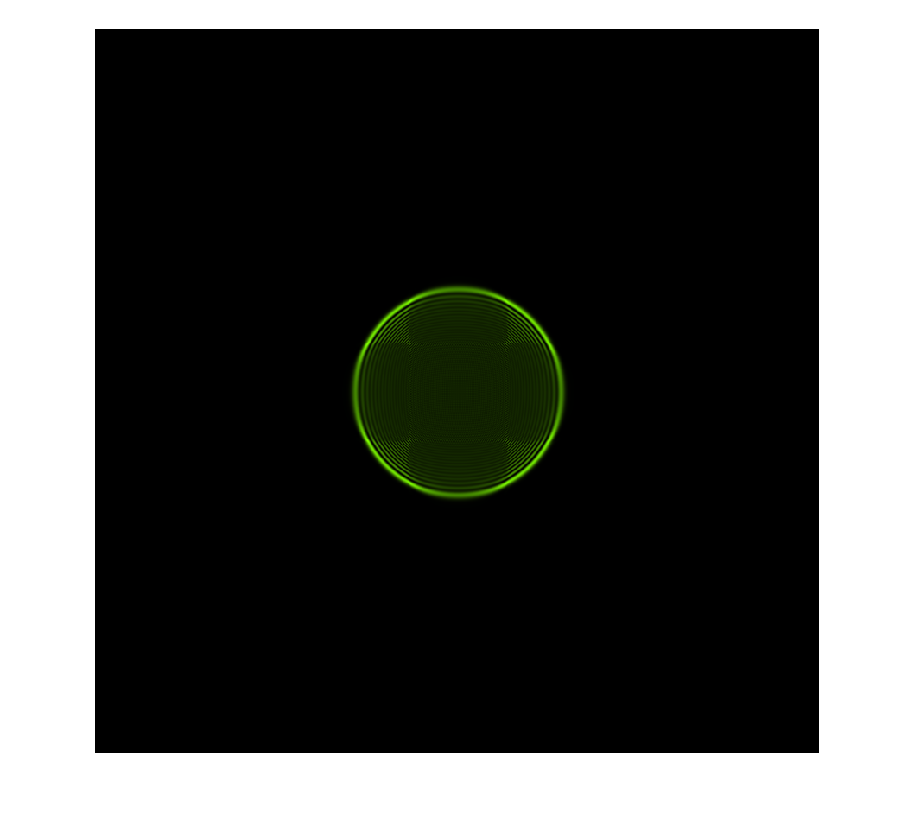

历时 0.302792 秒。


tic
for ii=1:1
    %叠加随机相位
    %F=FT2Dc(beams);
    %{
    if mod(ii,2)
        [phase1,phase2]=Diffuser.generateDiffuser(diffuser,rate,[N*num,N*num]);
        F=beams.*phase1;
    else
        F=beams.*phase2;
    end
    %}
    %F=FT2Dc(F);
    F = transform(beams, area1, lambda, 20, [rate, rate]);
    afterLens=ASMinLens(F,MLA1,lambda,area1);
    F = transform(afterLens, area2, lambda, distance1, [rate, rate]);
    %{
    afterLens = ASMinLens(F,FL,lambda,area2);
    F = transform(afterLens, area2, lambda, distance2, [rate, rate]);
    afterLens = ASMinLens(F,MLA2,lambda,area3);
    F = transform(afterLens, area3, lambda, distance3, [rate, rate]);
    F=FT2Dc(F);
    F=mask.*F;
    F=FT2Dc(F);
    %}
    I = I+abs(F).^2;
    %disp(ii)
    %subplot(2,2,1.5)
    Inorm=gather((I-min(I,[],'all'))./(max(I,[],'all')-min(I,[],'all')));
    II=gray2rgb(Inorm,color);
    imshow(II,[])
    %{
    if mod(ii,20)==0
        meanFWHM=calMeanDia(Inorm,gather(ceil(d_ex/rate)*0.75),0.13)*rate3;
        disp(['平均FWHM=' num2str(meanFWHM*1e6) 'nm'])
        peakmap=findPeak(Inorm);
        [row,~]=find(peakmap==1);
        disp(['光点数：' num2str(size(row,1))])
    end
    %}
    %{
    hist=imhist(Inorm);
    [~,peak(end+1)]=max(hist);
    SD(end+1)=std(Inorm,0,'all');
    subplot(2,2,3)
    plot(peak)
    subplot(2,2,4)
    plot(SD)
    %}
    drawnow
    toc
end

## 显示结果

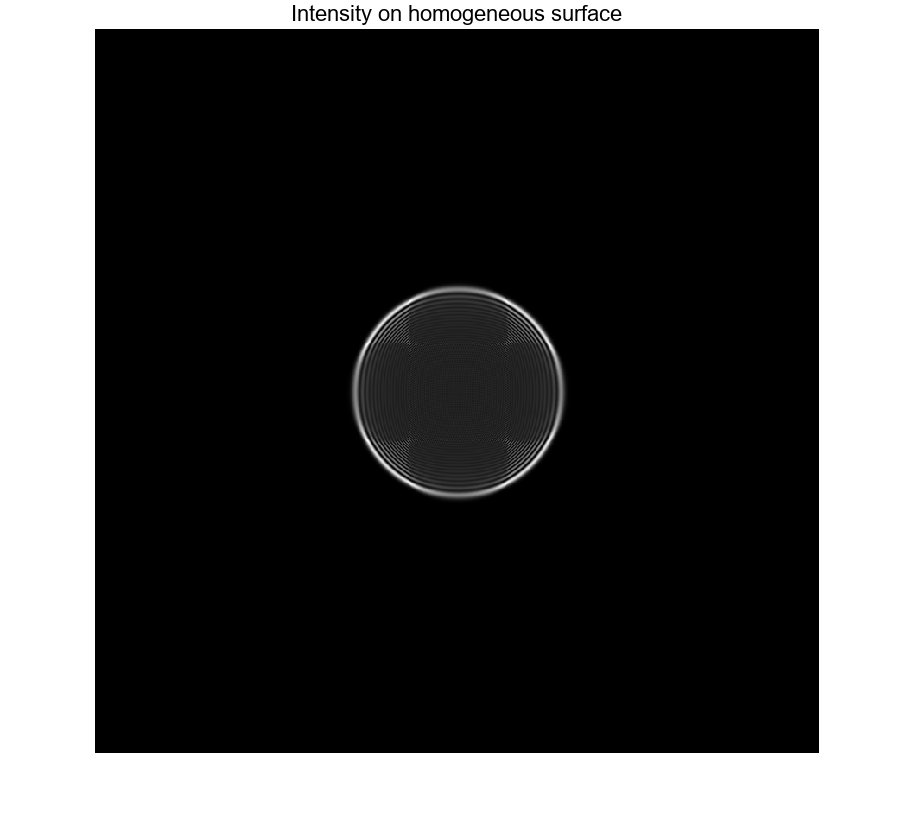

I = gather(I);
imshow(I, [])
title('Intensity on homogeneous surface')